Data Science (Prof. Neff)                Versuchsdatum 28.10.2020

Bestimmung der Viskosität von Spülmittel

Gruppe 6:    Benjamin Hamm (2060696), Jan Klotter (2060690),

                    Anna Kuhn (2051063), Michael Schulze (2061282)

Rohdaten der einzelnen Gruppenmitglieder

dataMichael = readtable("Blasen_Steigzeit_Michael.csv");
imageFrosch = imread("frosch_AleoVera_Spuellotion.png");
dataBenjamin = readtable("Blasen_Steigzeit_Benjamin.csv");
imageW5 = imread("W5_eco.png");
dataJan = readtable("Blasen_Steigzeit_Jan.csv");
dataAnna = readtable("Blasen_Steigzeit_Anna.csv");
imageEcover = imread("ecover_Colorwaschmittel.png");

disp("Messwerte Michael - Frosch Aloe Vera Spül-Lotion")

Messwerte Michael - Frosch Aloe Vera Spül-Lotion


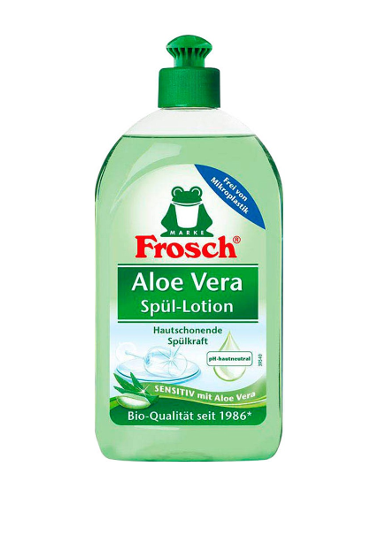

imshow(imageFrosch)

data = 10×2 table
    Blase_in_mm    Steigzeit_5cm_in_s
    ___________    __________________

          2                 19       
        3.5                9.8       
        3.5                9.7       
          3                8.8       
          2               21.5       
          4                  8       
          4                8.8       
          3                9.7       
        2.5                 22       
          3               11.5       


mittelwert = 1.2035

standardabweichung = 0.2735

standardunsicherheit = 0.0865

u_Vdreieck = 0.0012

u_Ddreieck = 6.1237e-04

dEta_dV =  -322.6618
 -262.8867
 -257.5490
 -155.7357
 -413.1591
 -228.8128
 -276.8635
 -189.2197
 -675.9362
 -265.9614


dEta_dR = 	1.0e+03 *

    1.6982
    1.5329
    1.5172
    1.1798
    1.9217
    1.4301
    1.5731
    1.3005
    2.4579
    1.5418


deltaEta =     1.1125
    0.9924
    0.9812
    0.7472
    1.2810
    0.9195
    1.0213
    0.8294
    1.7178
    0.9988


T = 10×6 table
      d           v          eta      deltaEta     reynold     turbulent
    ______    _________    _______    ________    _________    _________

     0.002    0.0026316    0.84911     1.1125     0.0063534      false  
    0.0035     0.005102     1.3413    0.99237      0.013647      false  
    0.0035    0.0051546     1.3276    0.98119      0.013929      false  
     0.003    0.0056818    0.88486    0.74724      0.019745      false  
     0.002    0.0023256    0.96083      1.281     0.0049618      false  
     0.004      0.00625     1.4301    0.91949      0.017919      false  
     0.004    0.0056818     1.5731     1.0213      0.014809      false  
     0.003    0.0051546    0.97536    0.82941      0.016251      false  
    0.0025    0.0022727     1.5362     1.7178     

ausgleichsgerade = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    ________    _________

    (Intercept)    -3.7679e-07    5.8891e-07    -0.63982      0.54018
    x1              0.00063237    0.00012578      5.0275    0.0010174


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 5.66e-07
R-squared: 0.76,  Adjusted R-Squared: 0.73
F-statistic vs. constant model: 25.3, p-value = 0.00102

steigung = 6.3237e-04

intercept = -3.7679e-07

se_v = 1.2578e-04

se_r_2 = 5.8891e-07

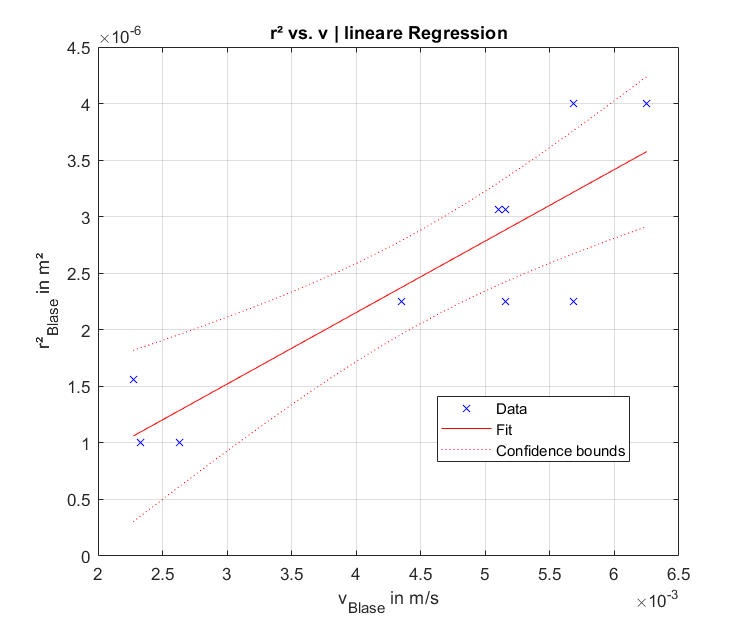

v = 0.5000

r_2 = 3.1619e-04

eta_linReg = 1.4130

dEta_dm = 2.2345e+03

deltaEta_LinReg = 0.0013

v = 9

p = 68.7200

t = 1.0600

Eta_Intervall1 =     1.1118    1.2952


t = 1.0600

ans =     "[0.849110 - 1.341259 * 1.327572 | 0.884862 + 0.960835 * 1.430080]
     [1.573088 - 0.975359 * 1.536219 | 1.156354 + 1.060000 * 1.112496]
     [0.992368 - 0.981192 * 0.747240 | 1.280959 + 0.919487 * 1.021253]
     [0.829411 - 1.717820 * 0.998769 | 0.849110 + 1.341259 * 1.327572]
     [0.884862 - 0.960835 * 1.430080 | 1.573088 + 0.975359 * 1.536219]
     [1.156354 - 1.060000 * 1.112496 | 0.992368 + 0.981192 * 0.747240]
     [1.280959 - 0.919487 * 1.021253 | 0.829411 + 1.717820 * 0.998769]
     "


Eta_Intervall3 =     1.4116    1.4144


[d1, v1, a1, b1] = eval_data(dataMichael);


disp("Messwerte Benjamin - W5 eco")

Messwerte Benjamin - W5 eco


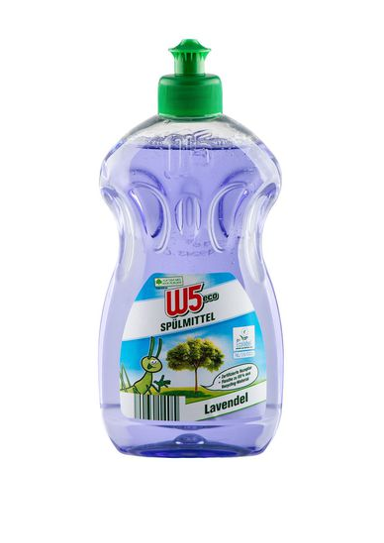

imshow(imageW5)

data = 10×2 table
    Blase_in_mm    Steigzeit_5cm_in_s
    ___________    __________________

          2                54        
          3                26        
          4                16        
          4                13        
        0.5               287        
        1.5                44        
        0.3               570        
          4                11        
          1                64        
          1                83        


mittelwert = 1.6301

standardabweichung = 0.8881

standardunsicherheit = 0.2809

u_Vdreieck = 0.0012

u_Ddreieck = 6.1237e-04

dEta_dV = 	1.0e+03 *

   -2.6063
   -1.3595
   -0.9153
   -0.6042
   -4.6013
   -0.9733
   -6.5339
   -0.4326
   -0.9153
   -1.5393


dEta_dR = 	1.0e+03 *

    4.8265
    3.4858
    2.8602
    2.3239
    6.4130
    2.9495
    7.6420
    1.9664
    2.8602
    3.7093


deltaEta =     4.3503
    2.7072
    2.0795
    1.6040
    6.8688
    2.1641
    9.2703
    1.3156
    2.0795
    2.9519


T = 10×6 table
      d           v           eta      deltaEta     reynold      turbulent
    ______    __________    _______    ________    __________    _________

     0.002    0.00092593     2.4133     4.3503     0.00078655      false  
     0.003     0.0019231     2.6144     2.7072      0.0022619      false  
     0.004      0.003125     2.8602     2.0795      0.0044796      false  
     0.004     0.0038462     2.3239      1.604      0.0067857      false  
    0.0005    0.00017422    0.80163     6.8688     0.00011138      false  
    0.0015     0.0011364     1.1061     2.1641      0.0015796      false  
    0.0003    8.7719e-05    0.57315     9.2703     4.7062e-05      false  
     0.004     0.0045455     1.9664     1.3156      0.0094776      false  
     0.001    0.00078125    0.

ausgleichsgerade = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)    -1.9038e-07    2.2687e-07    -0.83917       0.42574
    x1               0.0010673    9.9415e-05      10.736    4.9843e-06


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 4.73e-07
R-squared: 0.935,  Adjusted R-Squared: 0.927
F-statistic vs. constant model: 115, p-value = 4.98e-06

steigung = 0.0011

intercept = -1.9038e-07

se_v = 9.9415e-05

se_r_2 = 2.2687e-07

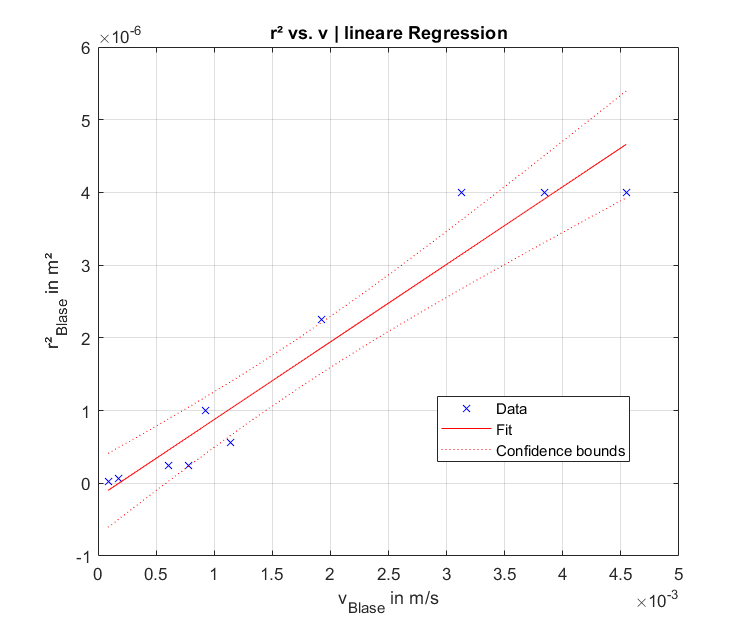

v = 0.5000

r_2 = 5.3364e-04

eta_linReg = 2.3848

dEta_dm = 2.2345e+03

deltaEta_LinReg = 5.0694e-04

v = 9

p = 68.7200

t = 1.0600

Eta_Intervall1 =     1.3324    1.9278


t = 1.0600

ans =     "[2.413260 - 2.614365 * 2.860160 | 2.323880 + 0.801627 * 1.106077]
     [0.573149 - 1.966360 * 0.715040 | 0.927317 + 1.060000 * 4.350299]
     [2.707183 - 2.079476 * 1.603982 | 6.868843 + 2.164146 * 9.270265]
     [1.315552 - 2.079476 * 2.951930 | 2.413260 + 2.614365 * 2.860160]
     [2.323880 - 0.801627 * 1.106077 | 0.573149 + 1.966360 * 0.715040]
     [0.927317 - 1.060000 * 4.350299 | 2.707183 + 2.079476 * 1.603982]
     [6.868843 - 2.164146 * 9.270265 | 1.315552 + 2.079476 * 2.951930]
     "


Eta_Intervall3 =     2.3843    2.3854


[d2, v2, a2, b2] = eval_data(dataBenjamin);


disp("Messwerte Jan - Frosch Aloe Vera Spül-Lotion")

Messwerte Jan - Frosch Aloe Vera Spül-Lotion


imshow(imageFrosch)

data = 10×2 table
    Blase_in_mm    Steigzeit_5cm_in_s
    ___________    __________________

         4                  10       
         2                16.7       
         2                  50       
         5                 1.9       
         3                12.5       
         3                16.7       
         2                16.7       
         2                  25       
         5                 2.5       
         5                   5       


mittelwert = 1.2194

standardabweichung = 0.5579

standardunsicherheit = 0.1764

u_Vdreieck = 0.0012

u_Ddreieck = 6.1237e-04

dEta_dV = 	1.0e+03 *

   -0.3575
   -0.2493
   -2.2345
   -0.0202
   -0.3142
   -0.5609
   -0.2493
   -0.5586
   -0.0349
   -0.1397


dEta_dR = 	1.0e+03 *

    1.7876
    1.4926
    4.4690
    0.4246
    1.6759
    2.2390
    1.4926
    2.2345
    0.5586
    1.1173


deltaEta =     1.1790
    0.9637
    3.8703
    0.2612
    1.0960
    1.5335
    0.9637
    1.5299
    0.3447
    0.7052


T = 10×6 table
      d         v          eta      deltaEta     reynold      turbulent
    _____    ________    _______    ________    __________    _________

    0.004       0.005     1.7876      1.179       0.011468      false  
    0.002    0.002994    0.74632    0.96369       0.008224      false  
    0.002       0.001     2.2345     3.8703     0.00091743      false  
    0.005    0.026316    0.53069    0.26116        0.25414      true   
    0.003       0.004     1.2569      1.096      0.0097859      false  
    0.003    0.002994     1.6792     1.5335      0.0054826      false  
    0.002    0.002994    0.74632    0.96369       0.008224      false  
    0.002       0.002     1.1172     1.5299      0.0036697      false  
    0.005        0.02    0.69828    0.34475        0.14679  

ausgleichsgerade = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate         SE        tStat      pValue  
                   __________    __________    ______    _________

    (Intercept)    1.3295e-06    5.6794e-07     2.341     0.047341
    x1             0.00023228    5.0487e-05    4.6007    0.0017538


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 1.3e-06
R-squared: 0.726,  Adjusted R-Squared: 0.691
F-statistic vs. constant model: 21.2, p-value = 0.00175

steigung = 2.3228e-04

intercept = 1.3295e-06

se_v = 5.0487e-05

se_r_2 = 5.6794e-07

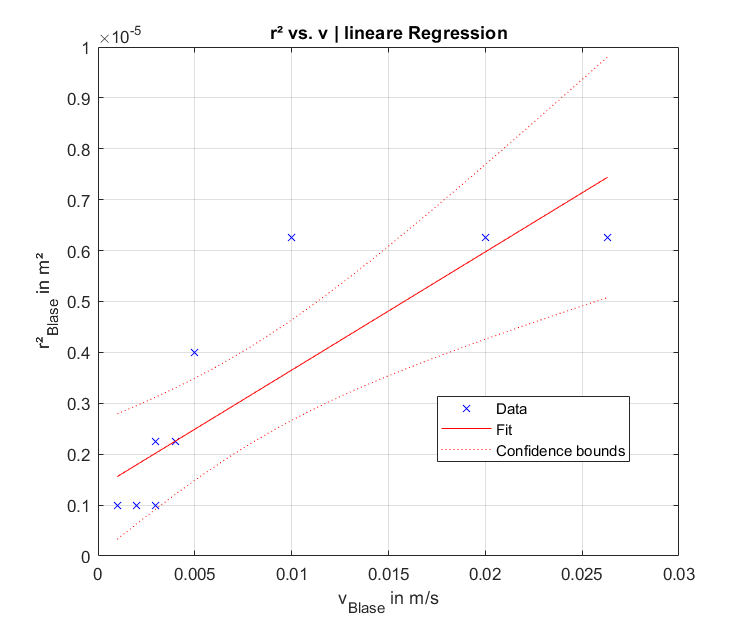

v = 0.5000

r_2 = 1.1614e-04

eta_linReg = 0.5190

dEta_dm = 2.2345e+03

deltaEta_LinReg = 0.0013

v = 9

p = 68.7200

t = 1.0600

Eta_Intervall1 =     1.0324    1.4064


t = 1.0600

ans =     "[1.787600 - 0.746323 * 2.234500 | 0.530694 + 1.256906 * 1.679227]
     [0.746323 - 1.117250 * 0.698281 | 1.396563 + 1.060000 * 1.179003]
     [0.963692 - 3.870268 * 0.261156 | 1.096046 + 1.533531 * 0.963692]
     [1.529858 - 0.344749 * 0.705229 | 1.787600 + 0.746323 * 2.234500]
     [0.530694 - 1.256906 * 1.679227 | 0.746323 + 1.117250 * 0.698281]
     [1.396563 - 1.060000 * 1.179003 | 0.963692 + 3.870268 * 0.261156]
     [1.096046 - 1.533531 * 0.963692 | 1.529858 + 0.344749 * 0.705229]
     "


Eta_Intervall3 =     0.5177    0.5204


[d3, v3, a3, b3] = eval_data(dataJan);


disp("Messwerte Anna - ecover Colorwaschmittel flüssig Konzentrat Apfelblüte & Freesie")

Messwerte Anna - ecover Colorwaschmittel flüssig Konzentrat Apfelblüte & Freesie


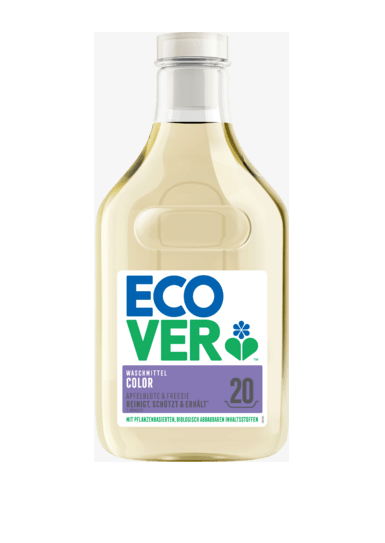

imshow(imageEcover)

data = 10×2 table
    Blase_in_mm    Steigzeit_5cm_in_s
    ___________    __________________

        1.5               15.2       
          1                 25       
          3               13.2       
          2               13.9       
          1                 20       
        0.5               33.3       
          3               13.1       
          3               13.9       
          5                  1       
        4.5                  2       


mittelwert = 0.6373

standardabweichung = 0.5099

standardunsicherheit = 0.1612

u_Vdreieck = 0.0012

u_Ddreieck = 6.1237e-04

dEta_dV =  -116.1582
 -139.6563
 -350.4054
 -172.6911
  -89.3800
  -61.9454
 -345.1163
 -388.5550
   -5.5862
  -18.0995


dEta_dR = 	1.0e+03 *

    1.0189
    1.1173
    1.7697
    1.2424
    0.8938
    0.7441
    1.7563
    1.8636
    0.2235
    0.4022


deltaEta =     0.6400
    0.7052
    1.1656
    0.7897
    0.5582
    0.4619
    1.1556
    1.2364
    0.1370
    0.2473


T = 10×6 table
      d           v          eta       deltaEta     reynold     turbulent
    ______    _________    ________    ________    _________    _________

    0.0015    0.0032895      0.3821    0.63998      0.013236      false  
     0.001        0.002     0.27931    0.70523     0.0073394      false  
     0.003    0.0037879      1.3273     1.1656     0.0087756      false  
     0.002    0.0035971     0.62119    0.78965      0.011871      false  
     0.001       0.0025     0.22345    0.55818      0.011468      false  
    0.0005    0.0015015    0.093011    0.46193     0.0082734      false  
     0.003    0.0038168      1.3172     1.1556       0.00891      false  
     0.003    0.0035971      1.3977     1.2364     0.0079139      false  
     0.005         0.05     0.27931    0

ausgleichsgerade = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE        tStat       pValue  
                   __________    _________    ______    __________

    (Intercept)    8.1028e-07    3.685e-07    2.1989      0.059097
    x1             0.00012196    2.059e-05    5.9232    0.00035241


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 9.7e-07
R-squared: 0.814,  Adjusted R-Squared: 0.791
F-statistic vs. constant model: 35.1, p-value = 0.000352

steigung = 1.2196e-04

intercept = 8.1028e-07

se_v = 2.0590e-05

se_r_2 = 3.6850e-07

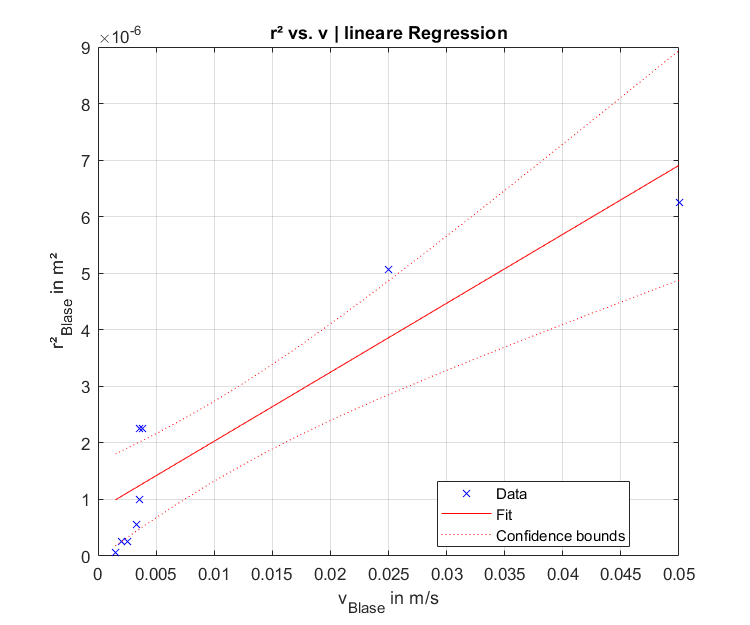

v = 0.5000

r_2 = 6.0978e-05

eta_linReg = 0.2725

dEta_dm = 2.2345e+03

deltaEta_LinReg = 8.2341e-04

v = 9

p = 68.7200

t = 1.0600

Eta_Intervall1 =     0.4664    0.8082


t = 1.0600

ans =     "[0.382099 - 0.279312 * 1.327293 | 0.621191 + 0.223450 * 0.093011]
     [1.317238 - 1.397680 * 0.279313 | 0.452486 + 1.060000 * 0.639979]
     [0.705229 - 1.165610 * 0.789652 | 0.558178 + 0.461932 * 1.155596]
     [1.236447 - 0.137006 * 0.247298 | 0.382099 + 0.279312 * 1.327293]
     [0.621191 - 0.223450 * 0.093011 | 1.317238 + 1.397680 * 0.279313]
     [0.452486 - 1.060000 * 0.639979 | 0.705229 + 1.165610 * 0.789652]
     [0.558178 - 0.461932 * 1.155596 | 1.236447 + 0.137006 * 0.247298]
     "


Eta_Intervall3 =     0.2716    0.2734


[d4, v4, a4, b4] = eval_data(dataAnna);

Plot aller Werte

disp("Plotten der Einzelwerte und Ausgleichsgeraden aller Gruppenmitglieder")

Plotten der Einzelwerte und Ausgleichsgeraden aller Gruppenmitglieder


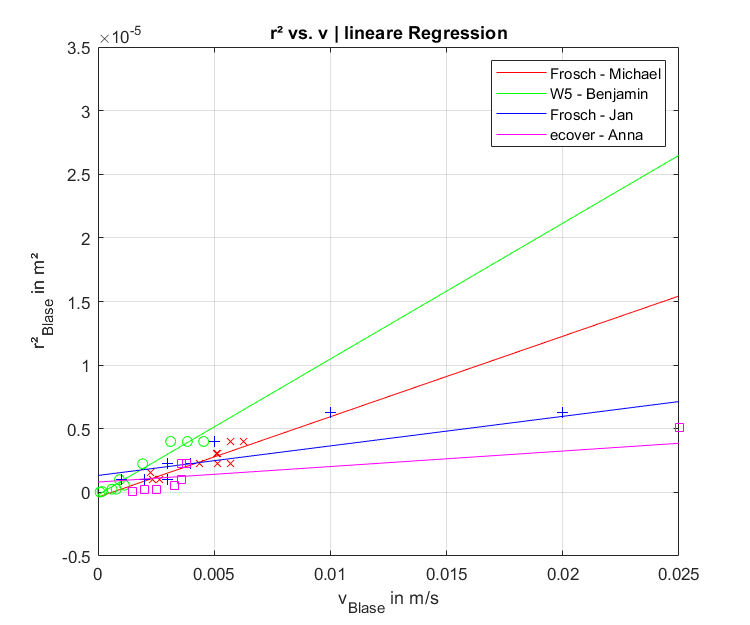

x = (0:1e-3:50*1e-3);

y1 = a1*x + b1;
y2 = a2*x + b2;
y3 = a3*x + b3;
y4 = a4*x + b4;

h1 = plot(x,y1, "r");
hold on;
    plot(v1,(d1 ./2).^2, "rx");

    h2 = plot(x,y2, "g");
    plot(v2,(d2 ./2).^2, "go");

    h3 = plot(x,y3, "b");
    plot(v3,(d3 ./2).^2, "b+");
    
    h4 = plot(x,y4, "m");
    plot(v4,(d4 ./2).^2, "ms");
    
    grid on;
    title('r² vs. v | lineare Regression');
    ylabel('r²_{Blase} in m²', 'Interpreter', 'tex');
    xlabel('v_{Blase} in m/s', 'Interpreter', 'tex');
    legend([h1 h2 h3 h4], {"Frosch - Michael","W5 - Benjamin", "Frosch - Jan","ecover - Anna"});
    set(gcf, 'position', [0.0000, -0.0000050, 600, 500])
    xlim([0.0000 0.025]);
    ylim([-0.0000050 0.0000350]);
hold off;

function [r_d, r_v, r_a, r_b] = eval_data(tmpdata)
    % Rückgabewerte sind Durchmesser d und Geschwindigkeit v
    % sowie Koeffizienten der Geradengleichung y = a*x + b
    data = tmpdata

            Konstanten

    s = 0.05;                    %Blasen wurden über einen Weg von 5 cm betrachtet
    g = 9.81;                    %m/s²
    %Vergleichswert Sicherheitsdatenblatt Frosch Aleo Vera Spül-Lotion
    etaDatenblatt = 1.500;       

            Steigzeit der Blasen für 5 cm in s

    t = data.Steigzeit_5cm_in_s;

            Geschwindigkeit der Blasen in m/s

    v = s ./ t;

            Durchmesser der Blasen in m

    d = data.Blase_in_mm .* 1e-3;
    
    r = d / 2;

            Dichte des Spülmittels in kg/m³

    %aus Sicherheitsdatenblatt Frosch Aleo Vera Spül-Lotion
    rho = 1025;

            Viskosität des Spülmittels in N*s/m²

    eta = (2*rho*g * (d ./2).^2) ./ (9 .* v);

            Statistische Kenngrößen der berechneten Viskosität

    mittelwert = mean(eta)
    standardabweichung = std(eta)
    standardunsicherheit = standardabweichung / sqrt(length(eta))

            Reynolds-Zahl zur Abschätzung der Strömung

    reynold = (v .* d .* rho) ./ (eta);
    %Kugeln ab Re > 0.2 als turbulente Strömung
    turbulent = reynold > 0.2;

            Abschätzung der Unsicherheiten

    %geschätzte Unsicherheit für Durchmesser 
    % 0.5 mm (Halber Milimeter nach Augenmaß abschätzbar)
    b_deltaD = 0.5 * 1e-3;
    %geschätzte Unsicherheit für Zeit 0.5 s 
    % (Genaugigkeit von 0.5 Sekunden durch Software bestimmbar)
    b_deltaT = 0.5;
    %geschätzte Unsicherheit für Geschwindigkeit m/s
    b_deltaV = b_deltaD / b_deltaT;
    
    %Dreieckverteilung Geschwindigkeit
    u_Vdreieck = b_deltaV / 2 * sqrt(6) 
    %Dreieckverteilung Durchmesser
    u_Ddreieck = b_deltaD / 2 * sqrt(6) 

            Fehlerfortpflanzung - Kombinierte Standardunsicherheit

    %Ableitung eta nach Geschwindigkeit
    dEta_dV = - (2 * r.^2 * g * rho) ./ (9 * v.^2)
    %Ableitung eta nach Radius
    dEta_dR = (4 * g * rho * r) ./ (9 * v)
    
    %Kombinierte Standardunsicherheit
    deltaEta = sqrt((dEta_dV .* u_Vdreieck).^2 + (dEta_dR .* u_Ddreieck).^2)

            Darstellung der Werte als Tabelle

    %varNames = {"d in m" "v in m/s" "eta in kg/m³" "delta eta" "Re" "Turbulent?"}
    T = table(d, v, eta, deltaEta, reynold, turbulent)

            Ausgleichsgerade (lineare Regression) von r² zu v

    ausgleichsgerade = fitlm(v,(d ./2).^2, "linear")
    steigung = ausgleichsgerade.Coefficients.Estimate(2)
    intercept = ausgleichsgerade.Coefficients.Estimate(1)
    se_v = ausgleichsgerade.Coefficients.SE(2)
    se_r_2 = ausgleichsgerade.Coefficients.SE(1)

            Plotten der Werte und Ausgleichsgeraden

    %plot(v,(d ./2).^2, "x")
    %hold on
        plot(ausgleichsgerade)
        grid on
        title('r² vs. v | lineare Regression')
        ylabel('r²_{Blase} in m²', 'Interpreter', 'tex')
        xlabel('v_{Blase} in m/s', 'Interpreter', 'tex')
        set(gcf, 'position', [0.0000, -0.0000050, 600, 500])
    %hold off

            Rückgabewerte

    r_d = d;
    r_v = v;
    r_a = steigung;
    r_b = intercept;
    
    %r.^2 = (9 * eta * v) / (2 * g * rho)
    
    %Zufallspunkt
    v = 0.5
    
    %Ausgleichsgerade Y-Wert zu Zufallspunkt
    r_2 = v * r_a
    
    eta_linReg = (r_2 * 2 * g * rho) / (9 * v)
    
    
    %Ableitung eta nach Steigung
    dEta_dm = (2 * g * rho) / 9
    %Ableitung eta nach Radius
    %dEta_dR = (4 * g * rho * sqrt(r_2)) / (9 * v)
    
    %Kombinierte Standardunsicherheit Lineare Regression
    deltaEta_LinReg = abs(dEta_dm * se_r_2)
    
    
    v = 9 %v = n - 1
    p = 68.72 %Aus Tabelle (GUM)
    t = 1.06 %Aus Tabelle (GUM)
    
    Eta_Intervall1 = [mittelwert - t * standardunsicherheit, mittelwert + t * standardunsicherheit]
    
    
   
    Eta_Intervall3 = [eta_linReg - t * deltaEta_LinReg, eta_linReg + t * deltaEta_LinReg]
    
end